# PCSSI Methods Based on Modal Identification of MDOF Systems

## Description of this Example

This code provides an example for running modal identification based on data obtained from open-source code available online. Specifically, the original data consist of simulated displacement responses generated using a simplified model of the Lysefjord Bridge [1–3]. The responses are simulated at five positions along the bridge span.

This code is a modified version based on the original work by E. Cheynet, the author of the open-source dataset. Our primary modification lies in the algorithm for constructing the state-space equations. To ensure a fair comparison in our paper, all algorithms use the same modal parameter identification approach based on the stabilization diagram clustering algorithm provided by E. Cheynet (version updated on 06/12/2019).

To simulate more realistic conditions, non-stationary Gaussian white noise is added to the original displacement response data. The objective is to estimate the modal frequencies, mode shapes, and modal damping ratios using the automated PCSSI (Principal Component Subspace Stochastic Identification) method.

The estimated results obtained from PCSSI are then compared against the true modal parameters in order to evaluate and verify the effectiveness of the proposed method.

References:

[1] Cheynet, E., Jakobsen, J. B., & Snæbjörnsson, J. (2016).Buffeting response of a suspension bridge in complex terrain. Engineering Structures, 128, 474-487.

[2] Cheynet, E., Jakobsen, J. B., & Snæbjörnsson, J. (2017).Damping estimation of large wind-sensitive structures.Procedia engineering, 199, 2047-2053.

[3] Cheynet, E., Snæbjörnsson, J., & Jakobsen, J. B. (2017).Temperature Effects on the Modal Properties of a Suspension Bridge.In Dynamics of Civil Structures, Volume 2 (pp. 87-93). Springer, Cham.

% Author: Biqi Chen

% Last modified: 31/3/2025

## Initialisation

Load simulated displacement data:

- *rz*: is the simulated vertical displacement response of the bridge in 5 positions along the span. It is a [5 x N] matrix

- *posSensors*: Is the position of the 5 sensors along the span. It is a [5 x 1] vector.

- *y*: Discrete span coordinates. It is a [Ny x 1] vector.

- *zetaStruct*: target modal damping ratios for the different modes of the structure. It is a [M x 1] vector.

- *phi*: target vertical mode shapes of the structure. It is a [M x 1] vector.

- *wn*: target vertical eigenmodes of the structure. It is a [M x 1] vector.

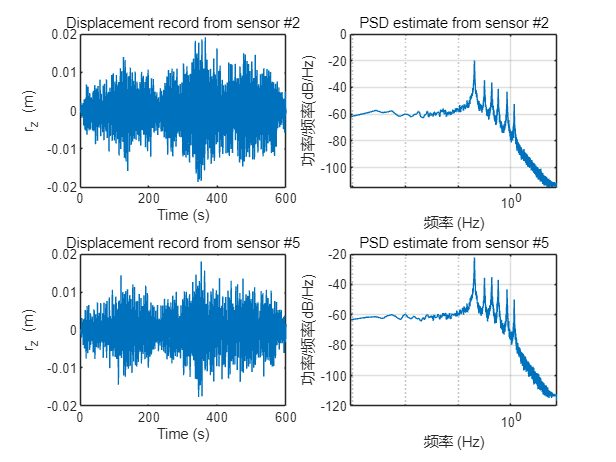

clearvars; close all; clc;

% Load bridge displacement data
load('BridgeData.mat', 't', 'rz', 'zetaStruct', 'phi', 'wn', 'posSensors', 'y');

% Convert circular natural frequencies (rad/s) to Hz
fnTarget = wn / (2 * pi);

% Compute time step and sampling frequency
dt = median(diff(t));     % Time step
fs = 1 / dt;              % Sampling frequency

% Get the size of the response matrix
[Nyy, N] = size(rz);      % Nyy: number of sensors, N: number of time steps

%% Visualization of the displacement response data

clf; close all;
figure

% Plot displacement time history from sensor #2
subplot(2, 2, 1)
plot(t, rz(2, :))
xlim([0, 600]);
xlabel('Time (s)')
ylabel('r_z (m)')
title('Displacement record from sensor #2')

% Plot PSD (Power Spectral Density) estimate from sensor #2
subplot(2, 2, 2)
pwelch(rz(2, :), [], [], [], 1/dt)
set(gca, 'xscale', 'log')
title('PSD estimate from sensor #2')

% Plot displacement time history from sensor #5
subplot(2, 2, 3)
plot(t, rz(5, :))
xlim([0, 600]);
xlabel('Time (s)')
ylabel('r_z (m)')
title('Displacement record from sensor #5')

% Plot PSD estimate from sensor #5
subplot(2, 2, 4)
pwelch(rz(5, :), [], [], [], 1/dt)
set(gca, 'xscale', 'log')
title('PSD estimate from sensor #5')


% Set figure background color to white
set(gcf, 'color', 'w')

To verify the effectiveness of the algorithm, non-stationary Gaussian noise is added to the original signal. To prominently highlight the noise robustness of the PCSSI method, the noise ratio is deliberately set to a relatively high value of 0.5.

% Function to add non-stationary Gaussian noise
function noisy_signal = add_nonstationary_gaussian_noise(signal, noise_ratio)
    % Add non-stationary Gaussian noise to a signal. 
    % The noise added to each sample is proportional to the magnitude 
    % of the signal at that point.
    %
    % Parameters:
    % - signal (array): The original input signal.
    % - noise_ratio (scalar): Ratio of noise amplitude to signal amplitude.
    %
    % Returns:
    % - noisy_signal (array): Signal with added non-stationary Gaussian noise.

    % Calculate noise standard deviation for each sample
    noise_std_per_sample = abs(signal) * noise_ratio;

    % Generate non-stationary Gaussian noise
    noise = noise_std_per_sample .* randn(size(signal));

    % Add noise to the original signal

历时 1.545146 秒。


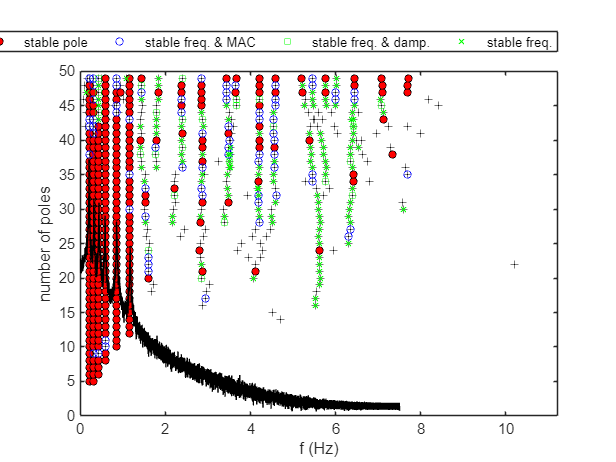

    noisy_signal = signal + noise;
end

% Define noise ratio

noise_ratio = 0.5;

% Add non-stationary Gaussian noise to the signal `rz`
noisy_rz = add_nonstationary_gaussian_noise(rz, noise_ratio);

## Application of PCSSI

The model order is varied between "Nmin" and "Nmax". 

The function PCSSI automatically estimates the modal parameters of the system based on the noisy displacement history "noisy_rz". 

The variable "paraPlot" is used to generate the stabilization diagram.

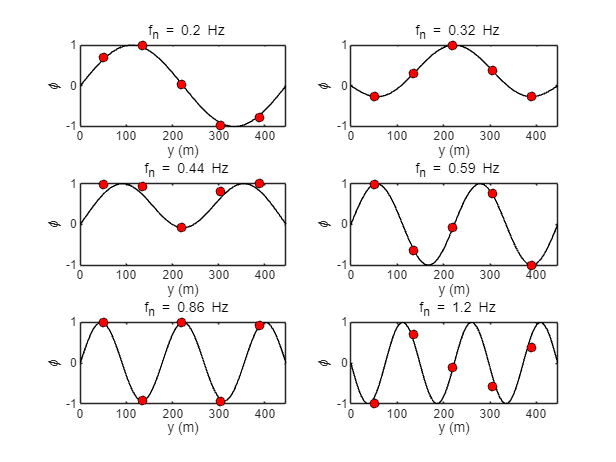

row_f = 18;     % Number of rows in the Yf matrix
col_f = 45000;  % Number of columns in the Yf matrix

row_p = 50;     % Number of rows in the Yp matrix
col_p = col_f;  % Number of columns in the Yp matrix

tic
[fn0, zeta0, phi0, paraPlot] = PCSSI(noisy_rz, dt, row_f, col_f, ...
                                     row_p, col_p, ...
                                     'Nmin', 5, 'Nmax', 50); % Call to PCSSI method
toc

## Plot  the stabilization diagram

The PSD estimate of the displacement response at the position no. 2 is superposed to the the identified poles.

clf;close all;
[h] = plotStabDiag(paraPlot.fn,rz(2,:),fs,paraPlot.status,paraPlot.Nmin,paraPlot.Nmax);

## Visualization of the identified mode shapes

The six mode shapes are properly identified, as shown below:

clf;close all;
figure

    Target    Estimate
    ______    ________

    0.005      0.0044 
    0.005      0.0046 
    0.005      0.0065 
    0.005      0.0062 
    0.005      0.0079 
    0.005      0.0297 



hold on

RMSE = @(y1,y2) sqrt(mean((y1-y2).^2));


    Target    Estimate
    ______    ________

    0.205      0.205  
    0.319      0.318  
    0.439      0.437  
    0.585      0.581  
    0.864      0.856  
    1.194      1.162  



clear ind
for ii=1:numel(fnTarget),
    subplot(3,2,ii)
    hold on;box on;
    plot(y,phi(ii,:),'k');
    [~,ind(ii)]=min(abs(fn0(ii)-fnTarget(1,:)));
    hold on;box on;
    
    
    % the identified mode shapes may have an opposite sign to the target mode shapes. 
    % This issue is corected by comparing the root-mean square error between the target and identified mode shapes.
    [~,indPos] = intersect(y,posSensors);
    if RMSE(phi(ii,indPos),phi0(ind(ii),:))>RMSE(phi(ii,indPos),-phi0(ind(ii),:)),
        plot(posSensors,-phi0(ind(ii),:),'ko','markerfacecolor','r')
    else
        plot(posSensors,phi0(ind(ii),:),'ko','markerfacecolor','r')
    end
    
    xlabel('y (m)')
    ylabel('\phi');
    title([' f_n = ',num2str(nanmean(fnTarget(:,ii)),2),' Hz'])
    axis tight
    ylim([-1,1])
end
set(gcf,'color','w')

## Comparison of the identified and target modal damping ratios

It is in general challenging to identify the modal damping ratios from ambient vibrations data. Therefore the agreement between the estimated and target modal damping ratios is here good.

T1 = table(zetaStruct(:),(round(zeta0(ind).*1e4)/1e4)','VariableNames',{'Target','Estimate'});
disp(T1)

## Comparison of the identified and target eigenfrequencies

The small discrepancies at higher frequencies between the identified and target eigenfrequencies do not come from the SSI-COV algorithm. They come from the numerical scheme used for the time-domain simulation of the bridge response, which relies on the Newmark-beta method. 

T2 = table((round(fnTarget(:).*1e3)/1e3),(round(fn0(ind).*1e3)/1e3)','VariableNames',{'Target','Estimate'});
disp(T2)
